dist_plots("DistancevsOutputFigures",DISTas,DISTveml);

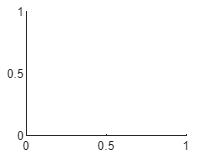

direc = "DistanceModelFigures";
d = 30:-5:5;
t_int = dictionary(1:6,[40, 80, 160, 320, 640, 1280]);
x = 5:0.1:30;
models = cell(2,6);
for t = 1:4
    DIST_AS = reshape(cell2mat(DISTas(:,t)),[],15);
    DIST_AS_CLEAR = DIST_AS(:,9);
    DIST_AS_Normalised = DIST_AS(:,1:9)./DIST_AS(6,1:9);
    DIST_AS_Normalised_CLEAR = DIST_AS_Normalised(:,9);

    f_AS = fit(d',DIST_AS_Normalised_CLEAR,'exp2');
    models{1,t} = f_AS;
    % -----------------------------------------------------
    DIST_VEML = reshape(cell2mat(DISTveml(:,t)),[],15);
    DIST_VEML_Normalised = DIST_VEML(:,11:14)./DIST_VEML(6,11:14);
    DIST_VEML_Normalised_CLEAR = DIST_VEML_Normalised(:,4);
    f_VEML = fit(d',DIST_VEML_Normalised_CLEAR,'exp2');
    models{2,t} = f_VEML;
    % -----------------------------------------------------
    f = figure();
    plot(d,DIST_AS_Normalised(:,1:9), 'LineWidth',1.2);
    hold on
    scatter(d,DIST_AS_Normalised(:,1:9), 30, AS_Colours, 'filled')
    grid on
    plot(x,f_AS(x), 'LineWidth', 1.2, 'LineStyle', '--','Color',[0.5 0.5 .5]);
    ax = gca;
    ax.ColorOrder = AS_Colours;

    xlabel("Distance (cm)",'FontSize',14);
    ylabel("Relative Response",'FontSize',14)
    plot_title = sprintf("AS7341 Relative Channel Responses with Distance Model");
    title(plot_title,'FontSize', 18)
    plot_subtitle = sprintf("t_{int} = %d ms, input colour = White", t_int(t));
    subtitle(plot_subtitle,'FontSize',12)
    AS_model = [AS_legend,"MODEL"];
    legend(AS_model,'Location','northeast','NumColumns',2);
    set(gcf,'units','normalized','outerposition',[0 0 0.4 0.6]);
    
    filename = sprintf("%s/AS_Normalised_%d_WHITE_distvcounts_model.jpg",direc,t_int(t));
    saveas(f,filename)
    close(f);
    hold off

    % -----------------------------------------------------
    f = figure();
    plot(d,DIST_VEML_Normalised(:,1:4), 'LineWidth',1.2);
    hold on
    scatter(d,DIST_VEML_Normalised(:,1:4), 30, VEML_Colours, 'filled')
    grid on
    plot(x,f_VEML(x), 'LineWidth', 1.2, 'LineStyle', '--','Color',[0.5 0.5 .5]);
    ax = gca;
    ax.ColorOrder = VEML_Colours;

    xlabel("Distance (cm)",'FontSize',14);
    ylabel("Relative Response",'FontSize',14)
    plot_title = sprintf("VEML6040 Relative Channel Responses with Distance Model");
    title(plot_title,'FontSize', 18)
    plot_subtitle = sprintf("t_{int} = %d ms, input colour = White", t_int(t));
    subtitle(plot_subtitle,'FontSize',12)
    VEML_model = [VEML_legend,"MODEL"];
    legend(VEML_model,'Location','northeast','NumColumns',2);
    set(gcf,'units','normalized','outerposition',[0 0 0.4 0.6]);
    
    filename = sprintf("%s/VEML_Normalised_%d_WHITE_distvcounts_model.jpg",direc,t_int(t));
    saveas(f,filename);
    close(f);
    hold off

    % -----------------------------------------------------

    model_AS_CLEAR = DIST_AS./f_AS(d);
    AS_CLEAR_mean = mean(model_AS_CLEAR);
    AS_CLEAR_dev = std(model_AS_CLEAR);

    f = figure();
    errorbar(1:9,AS_CLEAR_mean(1:9)./AS_CLEAR_mean(9),AS_CLEAR_dev(1:9)./AS_CLEAR_mean(9), 'LineStyle','none','Marker','o','MarkerSize', 3.5,"LineWidth",1.1,'Color',[0.7 0 1])
    grid on
    x_labels = {"CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR"};
    % xticks(0:10);
    xticklabels(x_labels);
    xlim([0.5,9.5])
    yticks(0:0.1:1);
    ylim([0,1.05]);
    xlabel("Channel",'FontSize',14);
    ylabel("Relative Response",'FontSize',14)
    plot_title = sprintf("AS7341 Relative Channel Responses to White Input");
    title(plot_title,'FontSize', 18)
    plot_subtitle = sprintf("t_{int} = %d ms, input colour = White", t_int(t));
    subtitle(plot_subtitle,'FontSize',12)
    set(gcf,'units','normalized','outerposition',[0 0 0.4 0.6]);

    filename = sprintf("%s/AS_ALL_Model_%d_Channel_Response_errorbar.jpg",direc,t_int(t));
    saveas(f,filename)
    close(f);

    % -----------------------------------------------------
    f = figure();
    errorbar(1:4,AS_CLEAR_mean([2,4,7,9])./AS_CLEAR_mean(9),AS_CLEAR_dev([2,4,7,9])./AS_CLEAR_mean(9), 'LineStyle','none','Marker','o','MarkerSize', 3.5, "LineWidth",1.1,'Color',[0.7 0 1])
    grid on
    x_labels = {"CH2","CH4","CH7","CLEAR"};
    xticks(1:4);
    xticklabels(x_labels);
    xlim([0.5,4.5])
    yticks(0:0.1:1);
    ylim([0,1.05]);

    xlabel("Channel",'FontSize',14);
    ylabel("Relative Response",'FontSize',14)
    plot_title = sprintf("AS7341 Relative Channel Responses to White Input");
    title(plot_title,'FontSize', 18)
    plot_subtitle = sprintf("t_{int} = %d ms, input colour = White", t_int(t));
    subtitle(plot_subtitle,'FontSize',12)
    set(gcf,'units','normalized','outerposition',[0 0 0.4 0.6]);

    filename = sprintf("%s/AS_Model_%d_Channel_Response_errorbar.jpg",direc,t_int(t));
    saveas(f,filename)
    close(f);

    % -----------------------------------------------------
    model_VEML_CLEAR = DIST_VEML./f_VEML(d);
    VEML_CLEAR_mean = mean(model_VEML_CLEAR(:,11:14));
    VEML_CLEAR_dev = std(model_VEML_CLEAR(:,11:14));

    f = figure();
    errorbar(1:4,VEML_CLEAR_mean./VEML_CLEAR_mean(4),VEML_CLEAR_dev./VEML_CLEAR_mean(4), 'LineStyle','none','Marker','o','MarkerSize', 3.5,"LineWidth",1.1,'Color',[0.7 0 1])
    grid on
    x_labels = {"RED", "GREEN", "BLUE", "CLEAR"};
    xticks(1:4)
    xticklabels(x_labels);
    xlim([0.5, 4.5])
    yticks(0:0.1:1);
    ylim([0,1.05])

    xlabel("Channel",'FontSize',14);
    ylabel("Relative Response",'FontSize',14)
    plot_title = sprintf("AS7341 Relative Channel Responses to White Input");
    title(plot_title,'FontSize', 18)
    plot_subtitle = sprintf("t_{int} = %d ms, input colour = White", t_int(t));
    subtitle(plot_subtitle,'FontSize',12)
    set(gcf,'units','normalized','outerposition',[0 0 0.4 0.6]);

    filename = sprintf("%s/VEML_Model_%d_Channel_Response_errorbar.jpg",direc,t_int(t));
    saveas(f,filename)
    close(f);
end

function dist_plots(direc,DISTas,DISTveml)
    AS_legend = ["CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR"];
    VEML_legend = ["RED", "GREEN", "BLUE", "CLEAR"];
    AS_Colours = [0.7 0 1; 0 0 1; 0 1 1; 0 1 0; 1 1 0; 1 0.6 0; 1 0 0; 0.7 0 0; 0 0 0];
    VEML_Colours = [1 0 0; 0 1 0; 0 0 1; 0 0 0];
    d = 30:-5:5;
    t_int = dictionary(1:6,[40, 80, 160, 320, 640, 1280]);

    for t = 1:4
        DIST_AS = reshape(cell2mat(DISTas(:,t)),[],15);
        DIST_AS_Normalised = DIST_AS(:,1:9)./DIST_AS(6,1:9);
        
        DIST_VEML = reshape(cell2mat(DISTveml(:,t)),[],15);
        DIST_VEML_Normalised = DIST_VEML(:,11:14)./DIST_VEML(6,11:14);
        
        f = figure();
        plot(d,DIST_AS(:,1:9), 'LineWidth',1.2);
        grid on
        hold on
        scatter(d,DIST_AS(:,1:9), 30, AS_Colours, 'filled')
        hold off
        ax = gca;
        ax.ColorOrder = AS_Colours;
        
        xlabel("Distance (cm)",'FontSize',14);
        ylabel("Counts",'FontSize',14)
        plot_title = sprintf("AS7341 Channel Responses vs. Distance");
        title(plot_title,'FontSize', 18)
        plot_subtitle = sprintf("t_{int} = %d ms, input colour = White", t_int(t));
        subtitle(plot_subtitle,'FontSize',12)
        legend(AS_legend,'Location','northeast','NumColumns',2);
        set(gcf,'units','normalized','outerposition',[0 0 0.4 0.6]);
        
        filename = sprintf("%s/AS_%d_WHITE_distvcounts.jpg",direc,t_int(t));
        saveas(f,filename)
        close(f);
        
        
        f = figure();
        plot(d,DIST_AS_Normalised(:,1:9), 'LineWidth',1.2);
        grid on
        hold on
        scatter(d,DIST_AS_Normalised(:,1:9), 30, AS_Colours, 'filled')
        hold off
        ax = gca;
        ax.ColorOrder = AS_Colours;
        
        xlabel("Distance (cm)",'FontSize',14);
        ylabel("Counts",'FontSize',14)
        plot_title = sprintf("AS7341 Relative Channel Responses vs. Distance");
        title(plot_title,'FontSize', 18)
        plot_subtitle = sprintf("t_{int} = %d ms, input colour = White", t_int(t));
        subtitle(plot_subtitle,'FontSize',12)
        legend(AS_legend,'Location','northeast','NumColumns',2);
        set(gcf,'units','normalized','outerposition',[0 0 0.4 0.6]);
        
        filename = sprintf("%s/AS_Normalised_%d_WHITE_distvcounts.jpg",direc,t_int(t));
        saveas(f,filename)
        close(f);

        % -----------------------------------------------------      
        f = figure();
        plot(d,DIST_VEML(:,11:14), 'LineWidth',1.2);
        hold on
        scatter(d,DIST_VEML(:,11:14), 30, VEML_Colours, 'filled')
        hold off
        grid on
        ax = gca;
        ax.ColorOrder = VEML_Colours;
        
        xlabel("Distance (cm)",'FontSize',14);
        ylabel("Counts",'FontSize',14)
        plot_title = sprintf("VEML6040 Channel Responses vs. Distance");
        title(plot_title,'FontSize', 18)
        plot_subtitle = sprintf("t_{int} = %d ms, input colour = White", t_int(t));
        subtitle(plot_subtitle,'FontSize',12)
        legend(VEML_legend,'Location','northeast','NumColumns',2);
        set(gcf,'units','normalized','outerposition',[0 0 0.4 0.6]);
        
        filename = sprintf("%s/VEML_%d_WHITE_distvcounts.jpg",direc,t_int(t));
        saveas(f,filename)
        close(f);
        
        % -----------------------------------------------------        
        f = figure();
        plot(d,DIST_VEML_Normalised(:,:), 'LineWidth',1.2);
        hold on
        scatter(d,DIST_VEML_Normalised(:,:), 30, VEML_Colours, 'filled')
        hold off
        grid on
        ax = gca;
        ax.ColorOrder = VEML_Colours;
        
        xlabel("Distance (cm)",'FontSize',14);
        ylabel("Counts",'FontSize',14)
        plot_title = sprintf("VEML6040 Relative Channel Responses vs. Distance");
        title(plot_title,'FontSize', 18)
        plot_subtitle = sprintf("t_{int} = %d ms, input colour = White", t_int(t));
        subtitle(plot_subtitle,'FontSize',12)
        legend(VEML_legend,'Location','northeast','NumColumns',2);
        set(gcf,'units','normalized','outerposition',[0 0 0.4 0.6]);
        
        filename = sprintf("%s/VEML_Normalised_%d_WHITE_distvcounts.jpg",direc,t_int(t));
        saveas(f,filename)
        close(f);
    end
end